# Advanced Application Development: Using Model-View-Controller Architecture

*Copyright 2025 The MathWorks, Inc.*

## Separated presentation design patterns help you work more effectively

Building an app programmatically gives significantly more control over the code structure and architecture. As apps grow in complexity, modular architecture and separation of concerns are important to achieve optimum performance, scalability, and testability. Additionally, following a standard software architecture pattern such as [model-view-controller](https://en.wikipedia.org/wiki/Model%E2%80%93view%E2%80%93controller) (MVC) as shown in Figure 1 enables you to build modular apps from smaller components, rather than having a single monolithic app file.

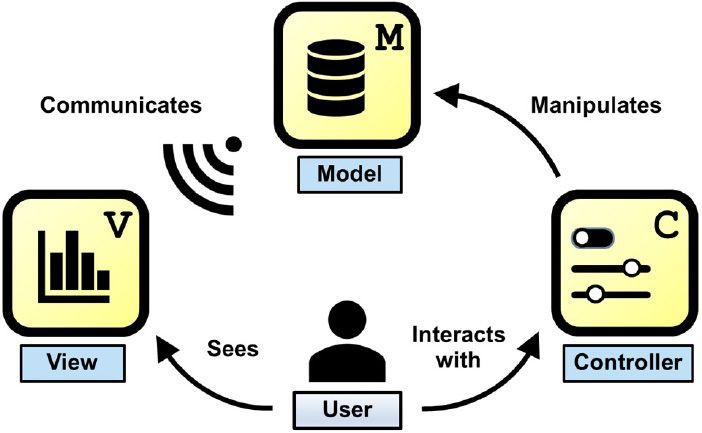

*Figure 1. The model-view-controller (MVC) software architecture pattern.*

For more information about using MVC architecture in MATLAB apps, please see the content below:

- Article: [Developing MATLAB Apps Using the Model-View-Controller Pattern - MATLAB & Simulink](https://www.mathworks.com/company/technical-articles/developing-matlab-apps-using-the-model-view-controller-pattern.html)

- Webinar: [Application Development Strategies in MATLAB - MATLAB](https://www.mathworks.com/videos/application-development-strategies-in-matlab-1689014110815.html)

- Training: [Advanced MATLAB Application Development - MATLAB & Simulink](https://www.mathworks.com/learn/training/advanced-matlab-application-development.html)

## Developing Model Classes

A model class has responsibilities to:

- Store relevant data for the application

- Store relevant states for the application

- Provide interfaces to the algorithms needed for the application

Model classes should generally be implemented as a handle class so that multiple components can reference the same model. Widgets Toolbox provides superclasses that extend `handle` to provide additional capabilities. These superclasses include [`wt.model.BaseModel`](matlab:open('..\+wt\+model\BaseModel.m')) and [`wt.model.BaseSession`](matlab:open('..\+wt\+model\BaseSession.m')). Using these is also necessary to work together with some other Widgets Toolbox classes including the view and controller superclasses that will be described later. These classes are shown below in Figure 2:

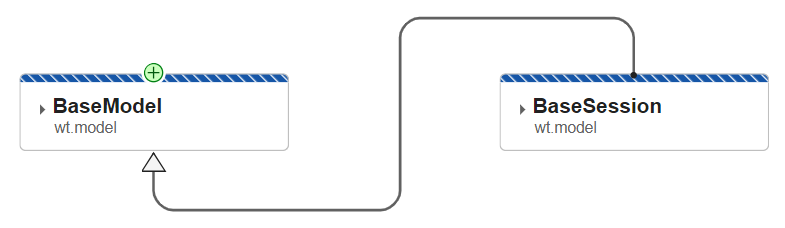

*Figure 2. BaseModel and BaseSession classes UML diagram*

The intended uses of these classes are:

- The class [`wt.model.BaseModel`](matlab:open('..\+wt\+model\BaseModel.m')) is needed when you utilize the view and controller superclasses [`wt.abstract.BaseViewController`](matlab:open('..\+wt\+abstract\BaseViewController.m')) and [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')) to implement modular application components. 

- The class [`wt.model.BaseSession`](matlab:open('..\+wt\+model\BaseSession.m')), which is a subclass of [`wt.model.BaseModel`](matlab:open('..\+wt\+model\BaseModel.m')), is needed when you use the top-level application superclasses [`wt.apps.BaseSingleSessionApp`](matlab:open('..\+wt\+apps\BaseSingleSessionApp.m')) or  [`wt.apps.BaseMultiSessionApp`](matlab:open('..\+wt\+apps\BaseMultiSessionApp.m')). These are described in [Reusable Superclasses for Hand-Code Apps](matlab:open('./AppSuperclasses.mlx')).

### Examples

#### BaseModel

The class zooexample[.model.Animal](matlab:open('..\examples\+wt\+example\+model\Animal.m')) implements a model class for a zoo animal's information. 

animal1 = zooexample.model.Animal;
animal1.Name = "Thomas";
animal1.Species = "Tiger";
animal1.Sex = "male";
animal1.BirthDate = "June 6, 2014"

animal1 =   Animal with properties:

      Species: "Tiger"
    BirthDate: 06-Jun-2014
          Sex: male
          Age: 10.5700
         Name: "Thomas"


#### BaseSession

The class zooexample[.model.Session](matlab:open('..\examples\+wt\+example\+model\Session.m')) implements model for a complete user session within the [Zoo Hierarchy Example App](matlab:open('..\examples\AdvancedAppZooHierarchyExample.mlx')).

session1 = zooexample.model.Session

session1 =   Session with properties:

        Exhibit: [0×1 wt.example.model.Exhibit]
       FileName: "untitled"
       FilePath: ""
    Description: ""
          Dirty: 0
           Name: "untitled"


## Developing View and Controller Classes

A view or controller class has several responsibilities:

- View: Display a representation of data in the model

- Controller: Provide a set of controls that manipulate model data or states

- Keep the displayed content or controls synchronized with the current state of the model

View and controller classes may be implemented using the [ChartContainer](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chartcontainer.chartcontainer-class.html) or [ComponentContainer](https://www.mathworks.com/help/matlab/ref/matlab.ui.componentcontainer.componentcontainer-class.html) superclasses. However, Widgets Toolbox also  provides superclasses [`wt.abstract.BaseViewController`](matlab:open('..\+wt\+abstract\BaseViewController.m')) and [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')) that extend [ChartContainer](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chartcontainer.chartcontainer-class.html) and [ComponentContainer](https://www.mathworks.com/help/matlab/ref/matlab.ui.componentcontainer.componentcontainer-class.html) to provide additional capabilities. These also share a common mixin class [wt.mixin.ModelObserver](matlab:open('..\+wt\+mixin\ModelObserver.m')) that provides functionality to observe changes in a model class. These classes are shown below in Figure 3:

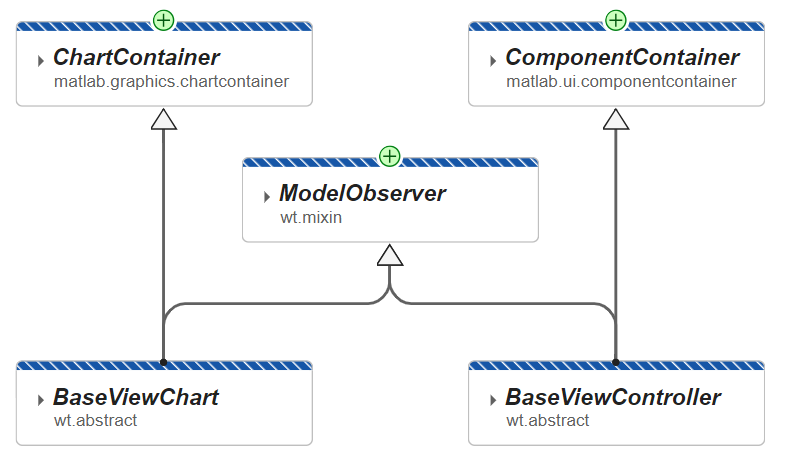

*Figure 3. BaseViewChart and BaseViewController classes UML diagram*

You can determine which superclass to use for your view or controller class based on the intended contents:

- The class  [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')) may be used when the view/controller to be placed in the `ContextualView` contains only axes and can be implemented as a [ChartContainer](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chartcontainer.chartcontainer-class.html) subclass. This is generally used as a view component only.

- The class  [`wt.abstract.BaseViewController`](matlab:open('..\+wt\+abstract\BaseViewController.m')) must be used when the view/controller to be placed in the `ContextualView` contains any combination of axes and app components and will be implemented as a [ComponentContainer](https://www.mathworks.com/help/matlab/ref/matlab.ui.componentcontainer.componentcontainer-class.html) subclass. This can be used for a view or controller component, or a mix of the two. 

Depending on the implementation, in MATLAB it is sometimes convenient to combine view and control components together in a hybrid component. Regardless of whether you are implementing a view, controller, or hybrid view/controller component, you should use the `BaseViewController` class unless your component would contain only axes for charting data.

### Examples

#### BaseViewController

The class zooexample[.view.Animal](matlab:open('..\examples\+wt\+example\+view\Animal.m')) implements a view/controller class for a zoo animal's information. 

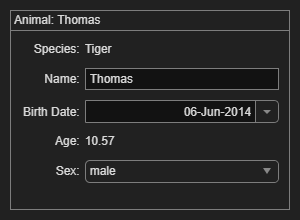

view1 =   Animal with properties:

       Model: [1×1 wt.example.model.Animal]
    Position: [0.0333 0.0455 0.9333 0.9091]

  Show all properties


fig = uifigure("Position",[100 100 300 220]);
g = uigridlayout(fig,[1 1]);
view1 = zooexample.view.Animal(g);
view1.Model = animal1

## Class Reference

### BaseModel

You must develop a concrete class using the superclass [`wt.model.BaseModel`](matlab:open('..\+wt\+model\BaseModel.m')) to utilize the view and controller superclasses [`wt.abstract.BaseViewController`](matlab:open('..\+wt\+abstract\BaseViewController.m')) and [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')) to implement modular application components. The following interface is implemented for [`wt.model.BaseModel`](matlab:open('..\+wt\+model\BaseModel.m')):

#### Events

#### Properties

#### Methods

### BaseSession

You must develop a concrete class using the superclass [`wt.model.BaseSession`](matlab:open('..\+wt\+model\BaseSession.m')) to utilize the application superclasses [`wt.apps.BaseSingleSessionApp`](matlab:open('..\+wt\+apps\BaseSingleSessionApp.m')) or  [`wt.apps.BaseMultiSessionApp`](matlab:open('..\+wt\+apps\BaseMultiSessionApp.m')). The app superclasses are described in [Reusable Superclasses for Hand-Code Apps](matlab:open('./AppSuperclasses.mlx')). 

`BaseSession` inherits the events, properties, and methods of `BaseModel`. The additional interface implemented in [`wt.model.BaseSession`](matlab:open('..\+wt\+model\BaseSession.m')) is shown below:

#### Events

#### Properties

#### Methods

### ModelObserver

ModelObserver is a mixin class that is utilized by both [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')) and [`wt.abstract.BaseViewController`](matlab:open('..\+wt\+abstract\BaseViewController.m')) to provide functionality to listen to state changes in a model class and notify your view or controller when an update is needed to synchronize the view to the current model state.

#### Events

#### Properties

#### Methods

### BaseViewChart

The following interface is implemented for [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')):

#### Properties

#### Methods

### BaseViewController

The following interface is implemented for [`wt.abstract.BaseViewController`](matlab:open('..\..\widgets\+wt\+abstract\BaseViewController.m')):

#### Properties

#### Methods

## Related Content

- Documentation: [Reusable Superclasses for Hand-Code Apps](matlab:open('..\..\widgets\doc\AppSuperclasses.html'))

- Documentation: [Contextual View Widget](matlab:open('../../widgets/examples/html/ContextualViewWidget.html'))

- App Example: [Zoo Hierarchy App Example](matlab:open('../../widgets/examples/html/AdvancedAppZooHierarchyExample.html'))

- Article: [Developing MATLAB Apps Using the Model-View-Controller Pattern - MATLAB & Simulink](https://www.mathworks.com/company/technical-articles/developing-matlab-apps-using-the-model-view-controller-pattern.html)

- Webinar: [Application Development Strategies in MATLAB - MATLAB](https://www.mathworks.com/videos/application-development-strategies-in-matlab-1689014110815.html)

- Training: [Advanced MATLAB Application Development - MATLAB & Simulink](https://www.mathworks.com/learn/training/advanced-matlab-application-development.html)

- Reference: [model-view-controller](https://en.wikipedia.org/wiki/Model%E2%80%93view%E2%80%93controller)